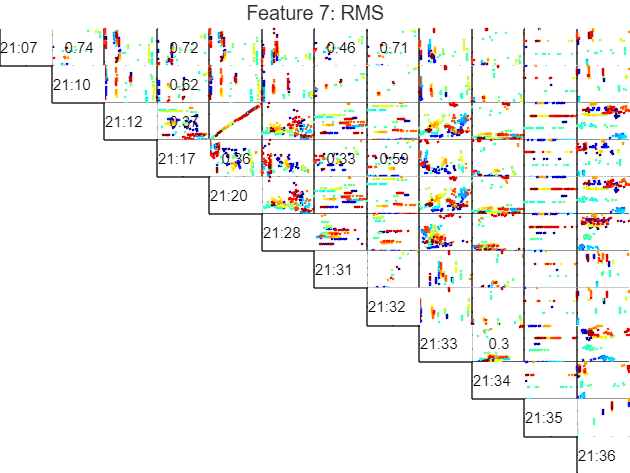

Features = DFD_FeatureTable_TimeDomain;
SignalNames = signalNames_Time;
FeatureNames = featureNames_Time;
lowerR2 = 0.3;
upperR2 = 0.8;
featureNum = 7; % RMS
R2 = fnPlotSignalVsSignal(Features, lowerR2, upperR2, featureNum, FeatureNames, SignalNames, sensorNames);        

disp(num2str(R2, '%.2f  '));

0.00  0.74  0.31  0.68  0.30  0.03  0.45  0.71  0.01  0.00  0.00  0.02
0.00  0.00  0.18  0.59  0.18  0.00  0.82  0.99  0.11  0.06  0.00  0.00
0.00  0.00  0.00  0.38  0.99  0.00  0.01  0.17  0.00  0.00  0.15  0.05
0.00  0.00  0.00  0.00  0.37  0.00  0.30  0.55  0.00  0.02  0.09  0.02
0.00  0.00  0.00  0.00  0.00  0.00  0.01  0.17  0.00  0.00  0.15  0.05
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.04  0.04  0.22  0.26
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.82  0.13  0.11  0.02  0.01
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.13  0.07  0.00  0.00
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.21  0.03  0.04
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.01
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.76
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  1.00


selectedSignal = 1; % row 1
[selectedSignalArray, selectedSignalData, numOfSelectedSignals] = fnSelectFeatures(selectedFeature, selectedSignal, featureArray, R2, upperR2, lowerR2);
disp(selectedSignalArray);

     1     2     3     4     5     7     8



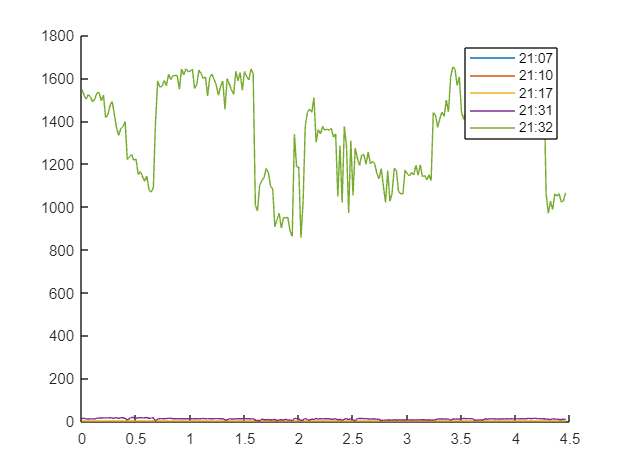

n = size(selectedSignalData{1}, 1);
t = ( 0 : 1/fs : (n / fs) - 1/fs)';
figure(); hold on
leg = {numOfSelectedSignals};
for i = 1:numOfSelectedSignals
    plot(t, selectedSignalData{i});
    txtTemp = char(sensorNames(selectedSignalArray(i)));
    leg{i} = char(txtTemp(1:5));
end
legend(leg);

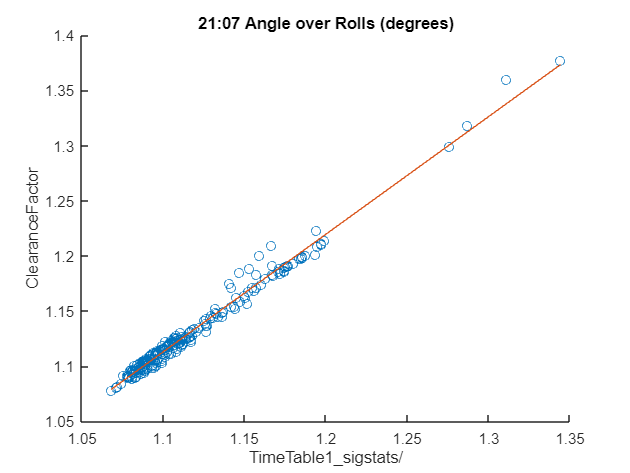

FIT = 87.21

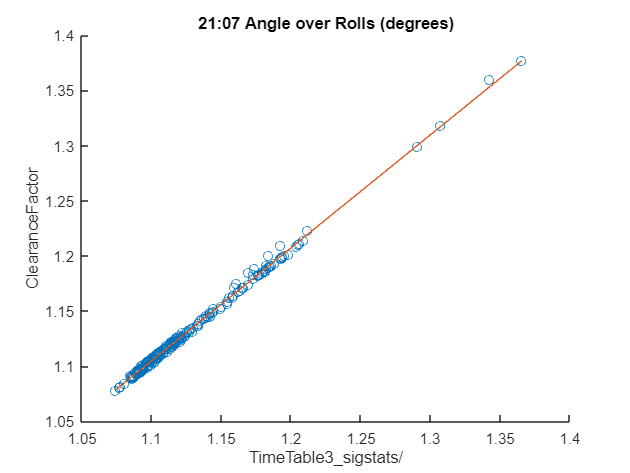

FIT = 94.95

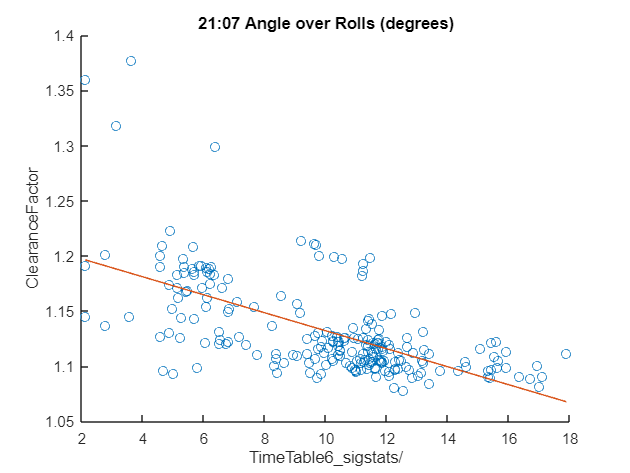

FIT = 21.46

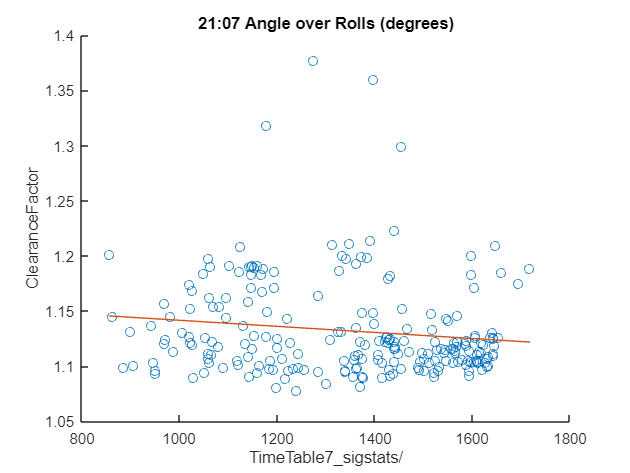

FIT = 0.94

for index = 1 : numOfSelectedSignals
    if index ~= selectedSignal
        fnPlotModel(selectedSignalData{selectedSignal}, selectedSignalData{index}, sensorNames(selectedSignal), FeatureNames(selectedSignalArray(selectedSignal)), SignalNames(selectedSignalArray(index)));
    end
end

1 2 3

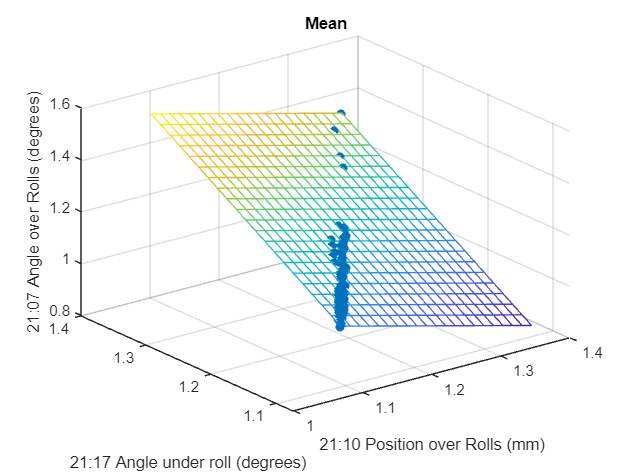

FIT = 99.403682

1 2 4

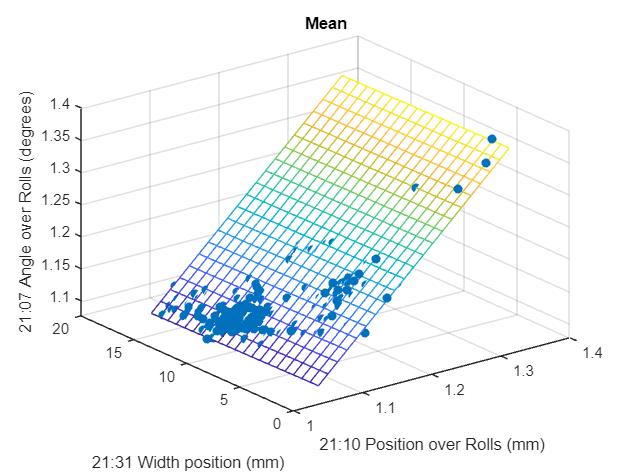

FIT = 87.295313

1 2 5

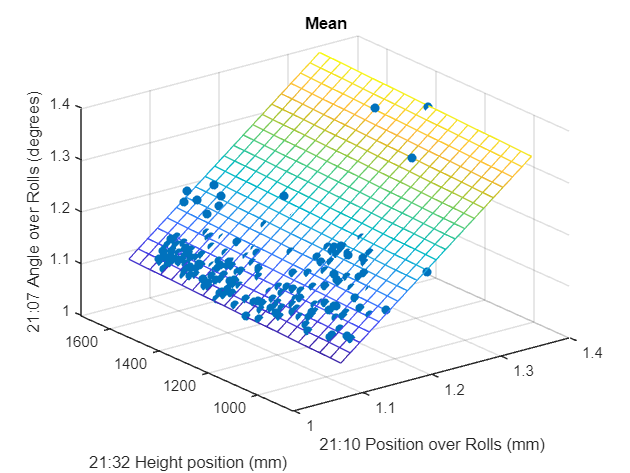

FIT = 91.603900

1 3 4

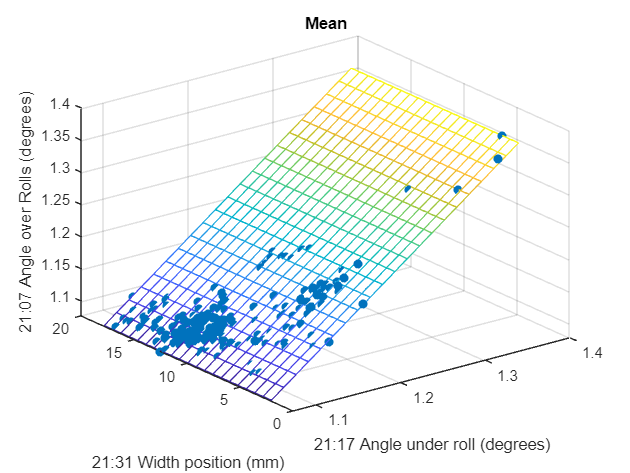

FIT = 94.952416

1 3 5

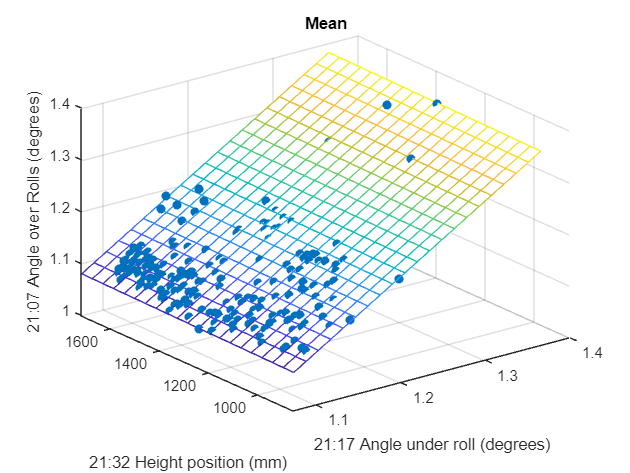

FIT = 96.879818

1 4 5

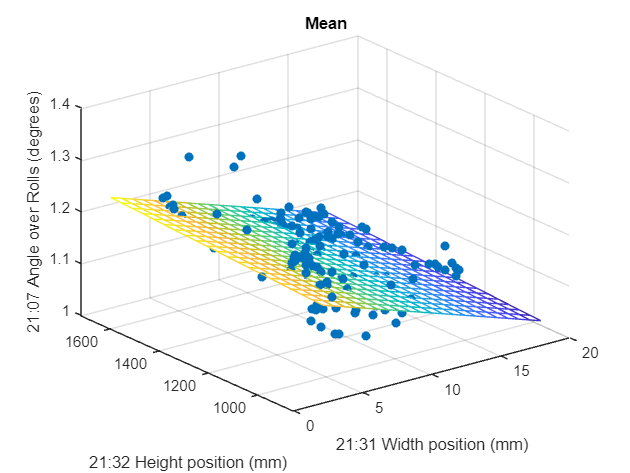

FIT = 22.515395

for index1 = 2 : numOfSelectedSignals
    for index2 = index1+1 : numOfSelectedSignals
        fprintf("%i %i %i", 1, index1, index2);
        Y_est = fnPlotModel3D( ...
            selectedSignalData{1}, ...
            selectedSignalData{index1}, ...
            selectedSignalData{index2}, ...
            FeatureNames(selectedFeature), ...
            sensorNames(selectedSignalArray(1)), ...
            sensorNames(selectedSignalArray(index1)), ...
            sensorNames(selectedSignalArray(index2)));
    end
end